## 改变形状

dlXGeneratedNew = cat(2,datastra,double(dlXGeneratedNew));
XTra = reshape(dlXGeneratedNew,lenaccelh,lenaccelw,numInputChannels,size(dlXGeneratedNew,2)); 
dlYGeneratedNew = cat(1,labeltra,double(dlYGeneratedNew));
YTra = categorical(dlYGeneratedNew);
% datasval = reshape(datasval,lenaccelh,lenaccelw,numInputChannels,size(datasval,2)); labelval = categorical(labelval);
% datastes = reshape(datastes,lenaccelh,lenaccelw,numInputChannels,size(datastes,2)); labeltes = categorical(labeltes);

## 定义CNN框架

filterSize = 9;
% 设置网络层
layers = [imageInputLayer([lenaccelh, lenaccelw, numInputChannels])  % 输入为一个样本

    convolution2dLayer([1, filterSize], 8, Padding="same")  % 卷积层的核[大小]、数量，填充方式
    batchNormalizationLayer("Name", "batchnorm_1")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([1, 2], "Name", "maxpool_1")  % 池化的尺寸

    convolution2dLayer([1, filterSize], 16, Padding="same")  % 卷积层的核[大小]、数量，填充方式
    batchNormalizationLayer("Name", "batchnorm_2")
    reluLayer("Name","relu_2")
    maxPooling2dLayer([1, 2], "Name", "maxpool_2")  % 池化的尺寸

    convolution2dLayer([1, filterSize], 8, Padding="same")  % 卷积层的核[大小]、数量，填充方式
    batchNormalizationLayer("Name", "batchnorm_3")
    reluLayer("Name","relu_3")
    maxPooling2dLayer([1, 2], "Name", "maxpool_3")  % 池化的尺寸
    
    dropoutLayer(0.5,"Name","dropout_1")
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];  % 添加回归层，用于计算损失

## 定义网络参数并开始训练

maxEpochs = 100;
miniBatchSize = 256;
validationFrequency = floor(length(XTra)/miniBatchSize);

options = trainingOptions('adam', ...
    'ExecutionEnvironment', 'gpu', ... 
    'L2Regularization', 0.001,...
    'InitialLearnRate', 0.001,...
    'LearnRateSchedule', 'piecewise',...
    'LearnRateDropPeriod', 4,...
    'LearnRateDropFactor', 0.90,...
    'MaxEpochs', maxEpochs, ...
    'MiniBatchSize', miniBatchSize, ...
    'ValidationData', {datasval, labelval}, ...
    'ValidationFrequency', validationFrequency, ... 
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress');

% 开始保存命令行窗口内容
diary("diary_1.txt")

% 打印系统时间
disp(datetime);

   2022-10-25 22:01:44



正在初始化输入数据归一化。


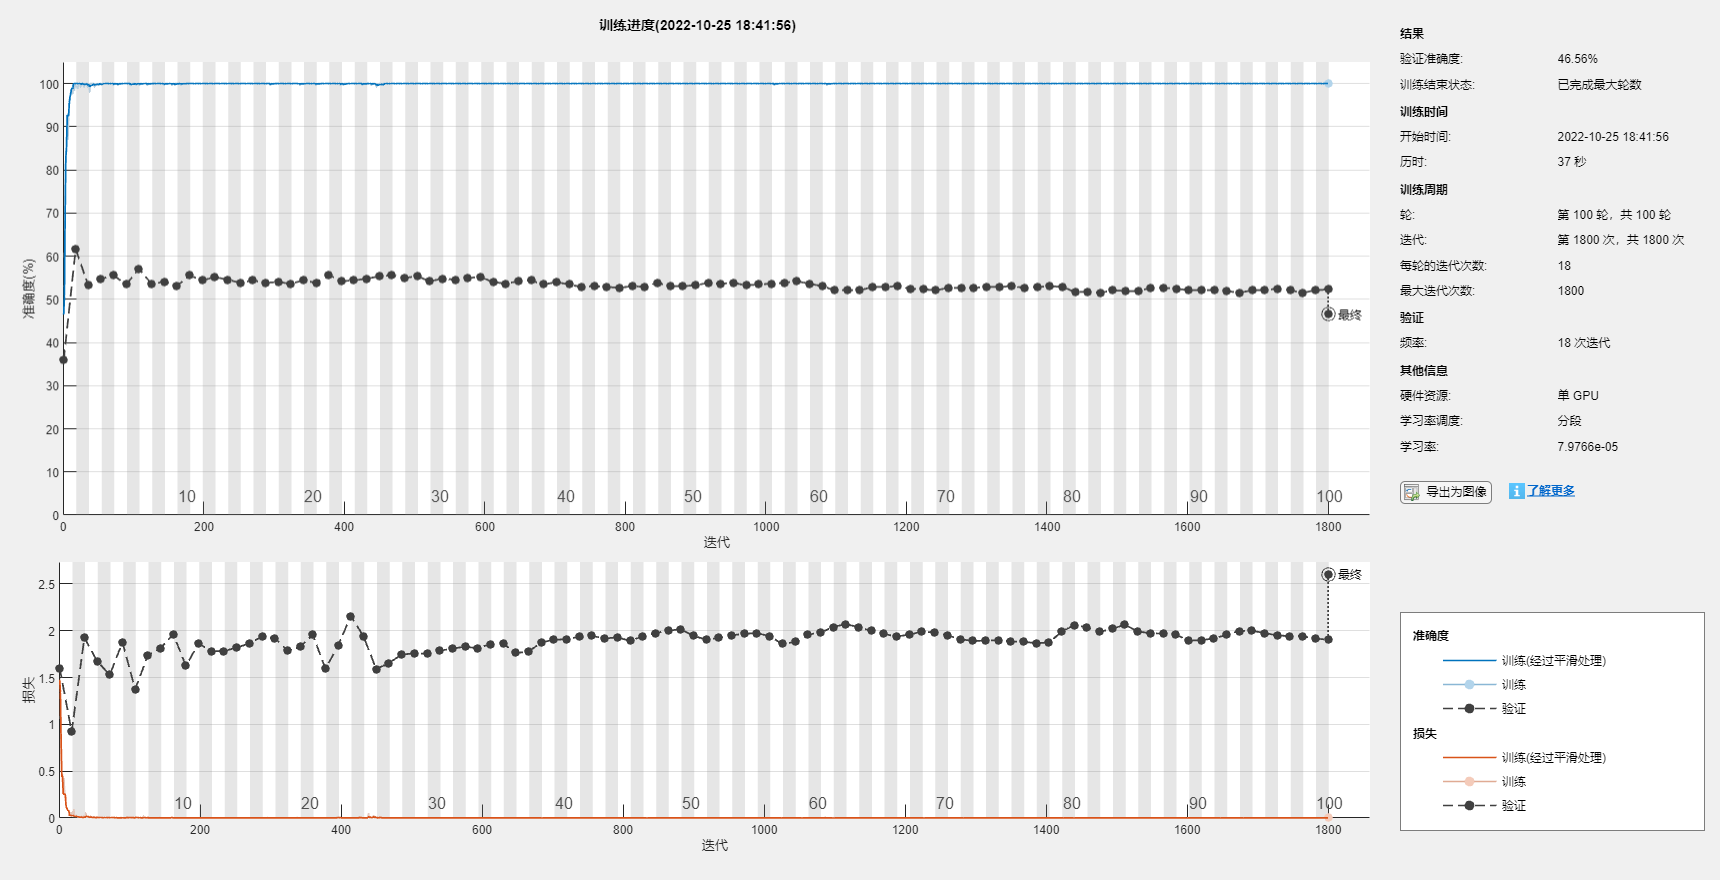


% 开始训练
[trainedNet,info] = trainNetwork(XTra, YTra, layers, options);


% 计算测试集正确率
YPred = classify(trainedNet, datastes);
zErrors = length(find((double(YPred) - double(labeltes))~=0));  % ~为不等于0.
zTestAccuracy = 1 - (zErrors/length(labeltes));
fprintf('本次训练预测错误：%d个，测试集正确率为：%2.2f%%\n', [zErrors zTestAccuracy*100])

本次训练预测错误：463个，测试集正确率为：58.59%


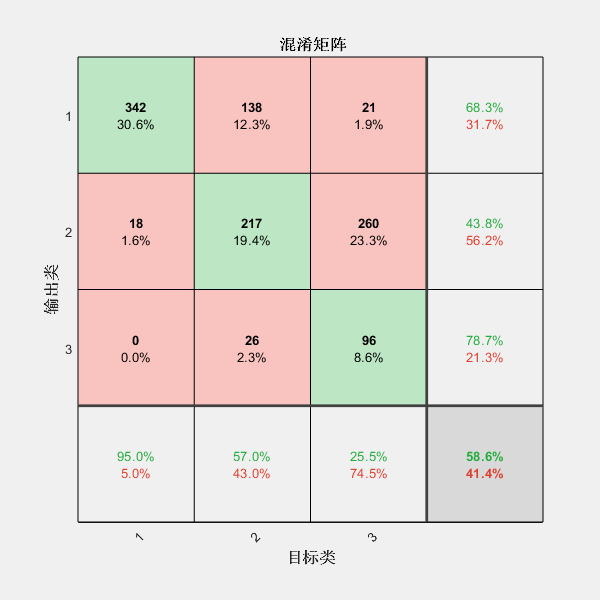


% 画混淆矩阵
cm = plotconfusion(labeltes, YPred);

cm.PaperPosition = [5, 5, 5.5, 5.5];
% print(cm, ['CM-2' '.png'],'-dpng','-r300')

% 打印系统时间
disp(datetime);

   2022-10-25 18:42:36




% 结束保存命令行窗口内容
diary off;